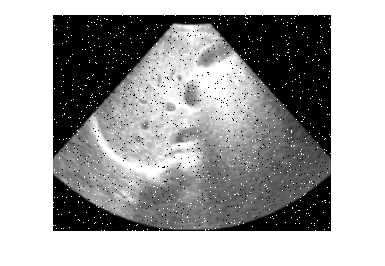

cd ~/Downloads/
liver = imread("liver_noisy_blurry.png");
figure, imshow(liver)

Denoise

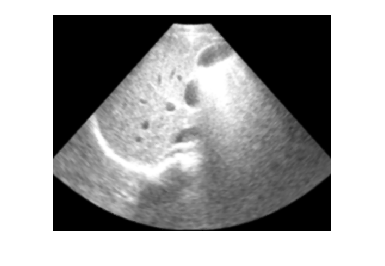

medianFilt = medfilt2(liver);
figure, imshow(medianFilt)

Deblur

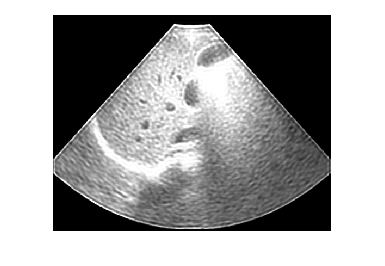

PSF = fspecial('gaussian',7,10);
deBlur = deconvblind(medianFilt, PSF);
figure, imshow(deBlur)

Enhance contrast

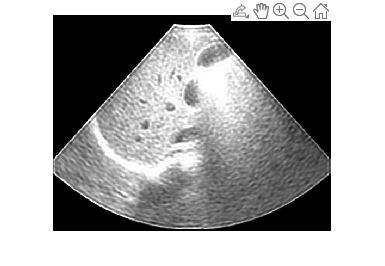

contrast = imadjust(deBlur);
figure, imshow(contrast)